% Load SAC collected sample range
% scenario = 'samp'
% 'A' for permutation stands for all samples
% SAC_perm = 'A'
% corr_perm = sprintf('%sA', SAC_perm)

scenario = 'range'

scenario = 'range'

SAC_perm = 'A25';
corr_perm = SAC_perm

corr_perm = 'A25'

% 
% SAC_samp_str = append('GVR_data/SAC_',scenario',SAC_perm,'.mat')
SAC_samp_str = sprintf('GVR_data/SAC_%s%s.mat', scenario, SAC_perm);

sigma_SAC_str = sprintf('GVR_data/corr_%s%s.mat', scenario, corr_perm);

filename = sprintf('GVR_data_code/%s%s.mat', scenario, corr_perm);
% SAC_samp = load('GVR_data/SAC_rangeA25.mat')
SAC_samp = load(SAC_samp_str);
x_SAC = transpose(SAC_samp.SAC);
y_SAC = transpose(SAC_samp.SAC);
SAC_samp = cat(2, x_SAC, y_SAC);

% Load SAC correlation matrix
% sigma_SAC = load('corr_poss0.mat')
% sigma_SAC = load('GVR_data/corr_rangeA20.mat')
sigma_SAC = load(sigma_SAC_str);
% corr_mat is a part of the struct
sigma_SAC = sigma_SAC.cor_mat

sigma_SAC =     1.0000    0.5983    0.5393    0.4862    0.4382    0.3950    0.3561    0.3210    0.2894    0.2608    0.2351    0.2120    0.1911    0.1722    0.1552    0.1399    0.1262    0.1137    0.1025    0.0924    0.0833    0.0751    0.0677    0.0610    0.0550
    0.5983    1.0000    0.5983    0.5393    0.4862    0.4382    0.3950    0.3561    0.3210    0.2894    0.2608    0.2351    0.2120    0.1911    0.1722    0.1552    0.1399    0.1262    0.1137    0.1025    0.0924    0.0833    0.0751    0.0677    0.0610
    0.5393    0.5983    1.0000    0.5983    0.5393    0.4862    0.4382    0.3950    0.3561    0.3210    0.2894    0.2608    0.2351    0.2120    0.1911    0.1722    0.1552    0.1399    0.1262    0.1137    0.1025    0.0924    0.0833    0.0751    0.0677
    0.4862    0.5393    0.5983    1.0000    0.5983    0.5393    0.4862    0.4382    0.3950    0.3561    0.3210    0.2894    0.2608    0.2351    0.2120    0.1911    0.1722    0.1552    0.1399    0.1262    0.1137    0.1025    0.0924    0

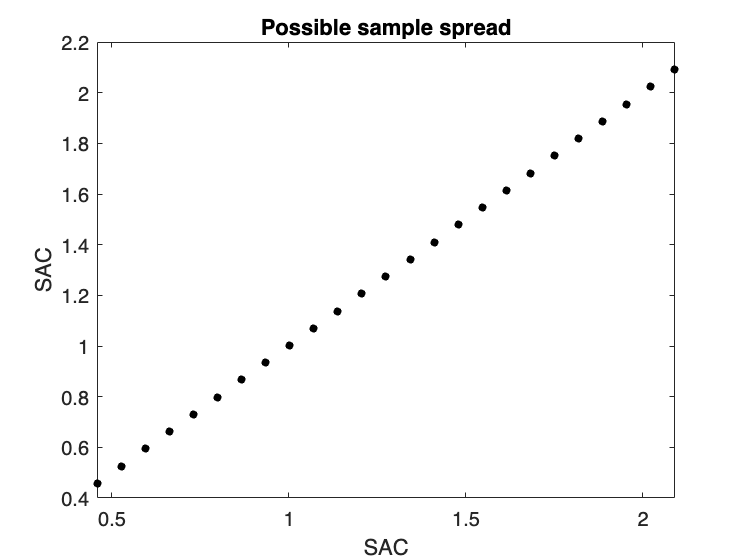


% Plot the possible sample selections (existing SSC field samples only)
figure
plot(SAC_samp(:,1), SAC_samp(:,2), 'k.', 'MarkerSize', 12)
xlabel('SAC')
ylabel('SAC')
title('Possible sample spread')


% Define ground set for the submodular function
SAC_V_sigma = 1:size(sigma_SAC, 1);

% Gaussian variance reduction function
F_mi2 = sfo_fn_varred(sigma_SAC, SAC_V_sigma);

% Now we will greedily pick sample measurements for maximizing MI
k = length(SAC_samp)

k = 25


% Pick sensors based on variance reduction
[A,scores,evals] = sfo_greedy_lazy(F_mi2, SAC_V_sigma, k)

A =     13     5    21     9    24     2    17    15     7    19    11     1    25     4    22    14     8    18    10    23     3    16     6    20    12


scores =     0.1801    0.2896    0.3976    0.4486    0.4984    0.5454    0.5918    0.6212    0.6500    0.6777    0.7044    0.7304    0.7564    0.7791    0.8019    0.8227    0.8433    0.8638    0.8837    0.9033    0.9230    0.9423    0.9615    0.9808    1.0000


evals =     25    25     4    22     6    10     4    16     4     9     6     6     2     8     2    11     6     3     6     4     2     4     4     2     2     0


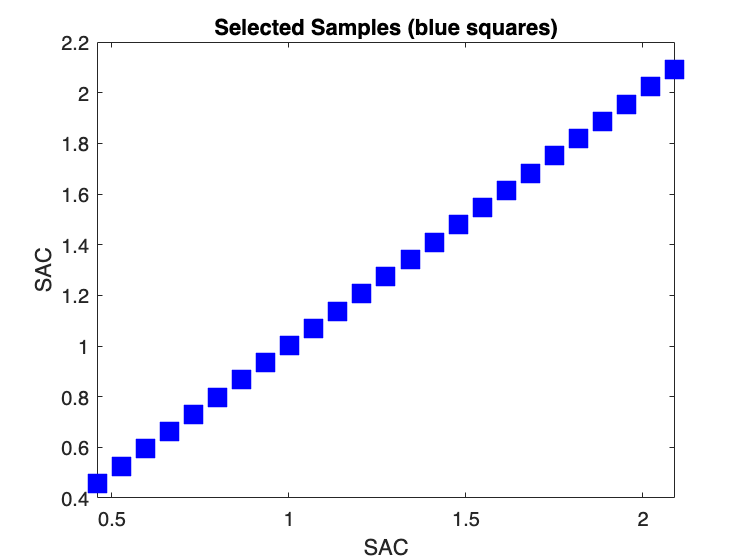

% Results give us same type of curve as MI

% Now let's display the chosen locations
figure 
plot(SAC_samp(:,1), SAC_samp(:,2), 'k.', 'MarkerSize', 12)
hold on
plot(SAC_samp(A,1), SAC_samp(A,2), 'bs','MarkerSize', 12, 'MarkerFaceColor', 'blue')
xlabel('SAC')
ylabel('SAC')
title('Selected Samples (blue squares)')


% save(filename,"A", "scores")

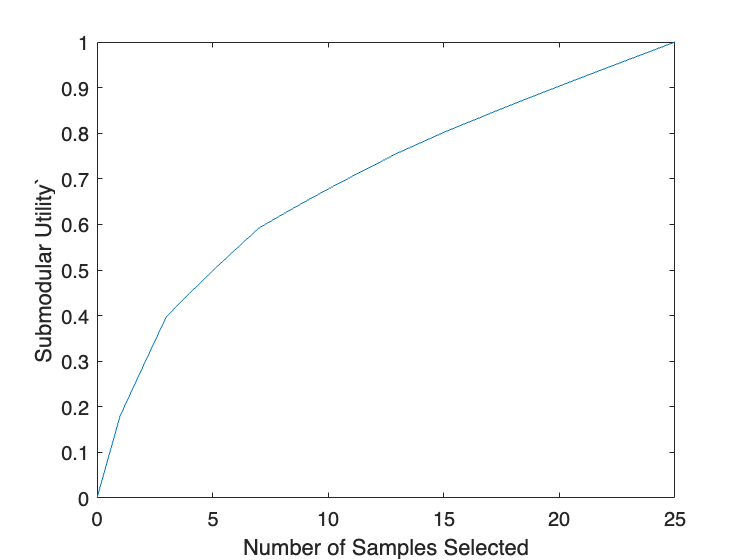

% Here's how the MI increases as we greedily pick more and more sensors
figure
plot(0:k,[0 scores])
xlabel('Number of Samples Selected')
ylabel('Submodular Utility`')